% This module calculates the year365 and divides the data into intervals of
% 5,10,20,30,50 years. It also plots the extreme periods in each interval.

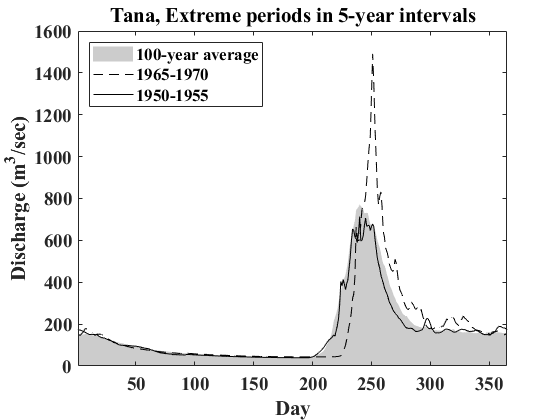

clc;
clear all;
close all;
clearvars;
warning('off')
stations={'name of sheet'}; % to be modified
filename = 'xlsx file location'; % contatining five columns of 1: date (dd/mm/yyy) 2:discharge data 3:day 4:month 5:year
[NUM,TXT,RAW] = xlsread(filename,stations{1});
n_day=[31 30 31 31 28 31 30 31 30 31 31 30];
mon=[10 11 12 1 2 3 4 5 6 7 8 9];
n_interval=5;
Year_start=[1910:n_interval:2010];
Year_end=[1915:n_interval:2015];
label={'100-year average','1910-1915','1915-1920','1920-1925','1925-1930','1930-1935','1935-1940','1940-1945','1945-1950','1950-1955','1955-1960','1960-1965','1965-1970','1970-1975','1975-1980','1980-1985','1985-1990','1990-1995','1995-2000','2000-2005','2005-2010','2010-2015',};
k=0;

    

for j=1:12
    for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j));
        avr(k,1)=mean(NUM(m,1));

    end
end
for j2=1:21 %change to j2=1:size(Year_start,2)
    k=0;
    for j=1:12
        for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j) & NUM(:,4)>=Year_start(j2) & NUM(:,4)<Year_end(j2));
        avr(k,j2+1)=mean(NUM(m,1));
        
        end
       
    end
     [max_dis(j2,1),I(j2,1)]=max(avr(:,j2+1));
end
[max_max_dis,Ind_max]=max(max_dis);
[min_max_dix,Ind_min]=min(max_dis);
x(:,1)=[1:365];
area(x,avr(:,1),'FaceColor',[0.8 0.8 0.8],'edgecolor','none'); hold 'on'
plot(x,avr(:,Ind_max+1),'Color',[0, 0, 0],"LineStyle","--"); hold 'on'
plot(x,avr(:,Ind_min+1),'Color',[0, 0, 0]); hold 'on'



labels=[label(1),label(Ind_max+1),label(Ind_min+1)];

legend(labels,'Location', 'northwest');
xlabel('Day')
ylabel('Discharge (m^3/sec)')
title('Tana, Extreme periods in 5-year intervals')
set(gca,'FontSize',14,'FontWeight','Bold', 'FontName','Times New Roman')
xlim([1 365]);
ylim([0 1600]);

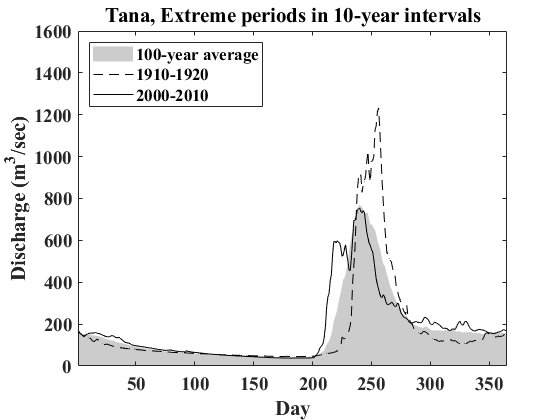


clc;
clear all;
close all;
clearvars;
stations={'name of sheet'}; % to be modified
filename = 'xlsx file location'; % contatining five columns of 1: date (dd/mm/yyy) 2:discharge data 3:day 4:month 5:year
[NUM,TXT,RAW] = xlsread(filename,stations{1});
n_day=[31 30 31 31 28 31 30 31 30 31 31 30];
mon=[10 11 12 1 2 3 4 5 6 7 8 9];
Year_start=[1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
Year_end=[1920 1930 1940 1950 1960 1970 1980 1990 2000 2010 2020];
label={'100-year average','1910-1920','1920-1930','1930-1940','1940-1950','1950-1960','1960-1970','1970-1980','1980-1990','1990-2000','2000-2010','2010-2020'};
k=0;

    

for j=1:12
    for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j));
        avr(k,1)=mean(NUM(m,1));

    end
end
for j2=1:11
    k=0;
    for j=1:12
        for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j) & NUM(:,4)>=Year_start(j2) & NUM(:,4)<Year_end(j2));
        avr(k,j2+1)=mean(NUM(m,1));
        
        end
       
    end
     [max_dis(j2,1),I(j2,1)]=max(avr(:,j2+1));
end
[max_max_dis,Ind_max]=max(max_dis);
[min_max_dix,Ind_min]=min(max_dis);
x(:,1)=[1:365];
area(x,avr(:,1),'FaceColor',[0.8 0.8 0.8],'edgecolor','none'); hold 'on'
plot(x,avr(:,Ind_max+1),'Color',[0, 0, 0],"LineStyle","--"); hold 'on'
plot(x,avr(:,Ind_min+1),'Color',[0, 0, 0]); 



labels=[label(1),label(Ind_max+1),label(Ind_min+1)];
legend(labels,'Location', 'northwest');
xlabel('Day')
ylabel('Discharge (m^3/sec)')
title('Tana, Extreme periods in 10-year intervals')
set(gca,'FontSize',14,'FontWeight','Bold', 'FontName','Times New Roman')
xlim([1 365]);
ylim([0 1600]);

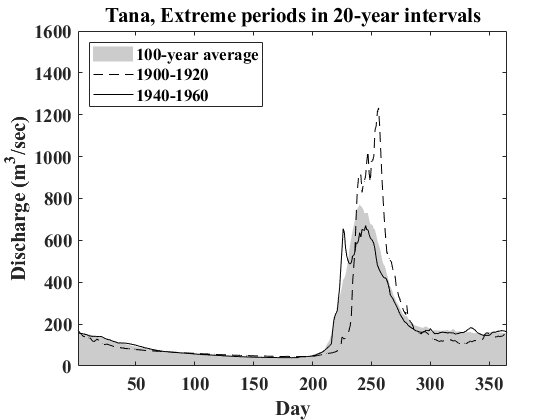

clc;
clear all;
close all;
clearvars;
stations={'name of sheet'}; % to be modified
filename = 'xlsx file location'; % contatining five columns of 1: date (dd/mm/yyy) 2:discharge data 3:day 4:month 5:year
[NUM,TXT,RAW] = xlsread(filename,stations{1});
n_day=[31 30 31 31 28 31 30 31 30 31 31 30];
mon=[10 11 12 1 2 3 4 5 6 7 8 9];
n_interval=20;
Year_start=[1900:n_interval:2000];
Year_end=[1920:n_interval:2020];
label={'100-year average','1900-1920','1920-1940','1940-1960','1960-1980','1980-2000','2000-2020'};
k=0;

    

for j=1:12
    for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j));
        avr(k,1)=mean(NUM(m,1));

    end
end
for j2=1:6
    k=0;
    for j=1:12
        for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j) & NUM(:,4)>=Year_start(j2) & NUM(:,4)<Year_end(j2));
        avr(k,j2+1)=mean(NUM(m,1));
        
        end
       
    end
     [max_dis(j2,1),I(j2,1)]=max(avr(:,j2+1));
end
[max_max_dis,Ind_max]=max(max_dis);
[min_max_dix,Ind_min]=min(max_dis);
x(:,1)=[1:365];
area(x,avr(:,1),'FaceColor',[0.8 0.8 0.8],'edgecolor','none'); hold 'on'
plot(x,avr(:,Ind_max+1),'Color',[0, 0, 0],"LineStyle","--"); hold 'on'
plot(x,avr(:,Ind_min+1),'Color',[0, 0, 0]); 


labels=[label(1),label(Ind_max+1),label(Ind_min+1)];
legend(labels,'Location', 'northwest');
xlabel('Day')
ylabel('Discharge (m^3/sec)')
title('Tana, Extreme periods in 20-year intervals')
set(gca,'FontSize',14,'FontWeight','Bold', 'FontName','Times New Roman')
xlim([1 365]);
ylim([0 1600]);

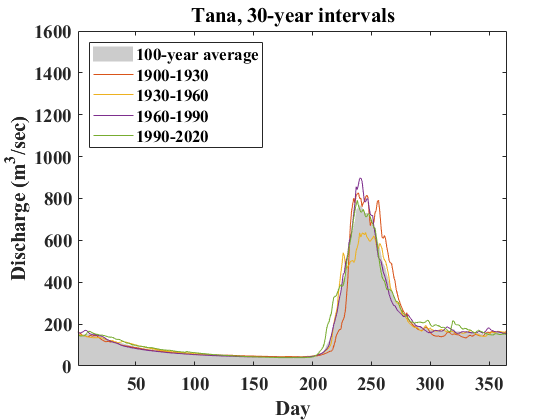

clc;
clear all;
close all;
clearvars;
stations={'name of sheet'}; % to be modified
filename = 'xlsx file location'; % contatining five columns of 1: date (dd/mm/yyy) 2:discharge data 3:day 4:month 5:year
[NUM,TXT,RAW] = xlsread(filename,stations{1});
n_day=[31 30 31 31 28 31 30 31 30 31 31 30];
mon=[10 11 12 1 2 3 4 5 6 7 8 9];
Year_start=[1900 1930 1960 1990];
Year_end=[1930 1960 1990 2020];
label={'100-year average','1900-1930','1930-1960','1960-1990','1990-2020'};
k=0;

    

for j=1:12
    for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j));
        avr(k,1)=mean(NUM(m,1));

    end
end
for j2=1:4
    k=0;
    for j=1:12
        for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j) & NUM(:,4)>=Year_start(j2) & NUM(:,4)<Year_end(j2));
        avr(k,j2+1)=mean(NUM(m,1));
        end
    end
end
x(:,1)=[1:365];
area(x,avr(:,1),'FaceColor',[0.8 0.8 0.8],'edgecolor','none'); hold 'on'
plot(x,avr(:,2)); hold 'on'
plot(x,avr(:,3)); hold 'on'
plot(x,avr(:,4)); hold 'on'
plot(x,avr(:,5)); 


labels=[label(1),label(2),label(3),label(4),label(5)];
legend(labels,'Location', 'northwest');
xlabel('Day')
ylabel('Discharge (m^3/sec)')
title('Tana, 30-year intervals')
set(gca,'FontSize',14,'FontWeight','Bold', 'FontName','Times New Roman')
xlim([1 365]);
ylim([0 1600]);

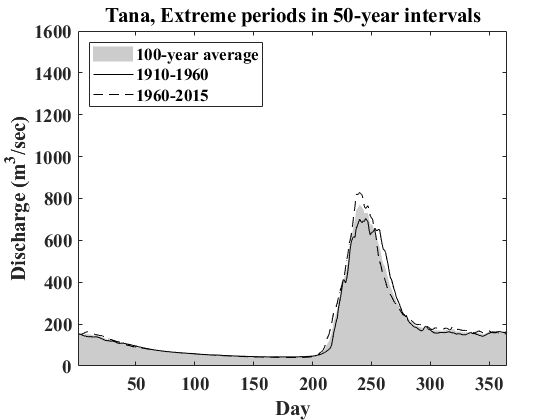

clc;
clear all;
close all;
clearvars;
stations={'name of sheet'}; % to be modified
filename = 'xlsx file location'; % contatining five columns of 1: date (dd/mm/yyy) 2:discharge data 3:day 4:month 5:year
[NUM,TXT,RAW] = xlsread(filename,stations{1});
n_day=[31 30 31 31 28 31 30 31 30 31 31 30];
mon=[10 11 12 1 2 3 4 5 6 7 8 9];
Year_start=[1910 1960];
Year_end=[1960 2015];
label={'100-year average','1910-1960','1960-2015'};
k=0;

    

for j=1:12
    for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j));
        avr(k,1)=mean(NUM(m,1));

    end
end
for j2=1:2
    k=0;
    for j=1:12
        for i=1:n_day(j)
        k=k+1;
        clear m n
        [m,n]=find(NUM(:,2)==i & NUM(:,3)==mon(j) & NUM(:,4)>=Year_start(j2) & NUM(:,4)<Year_end(j2));
        avr(k,j2+1)=mean(NUM(m,1));
        end
    end
end
x(:,1)=[1:365];
area(x,avr(:,1),'FaceColor',[0.8 0.8 0.8],'edgecolor','none'); hold 'on'
plot(x,avr(:,2),'Color',[0, 0, 0]); hold 'on'
plot(x,avr(:,3),'Color',[0, 0, 0],"LineStyle","--"); 


labels=[label(1),label(2),label(3)];
legend(labels,'Location', 'northwest');
xlabel('Day')
ylabel('Discharge (m^3/sec)')
title('Tana, Extreme periods in 50-year intervals')
set(gca,'FontSize',14,'FontWeight','Bold', 'FontName','Times New Roman')
xlim([1 365]);
ylim([0 1600]);